# **Controls for parameter tuning**

## Load experiment

% note : the experiment loaded here has been preprocessed for peak detection and
% rescaling. If this is not the case, you need to do it.
%% See script to change the default values across the demo scripts
STANDARD_INITIALIZATION();

answ = 'Reload'

	INFO : No change detected in time smoothing
	INFO : No change detected in time smoothing
	INFO : No change detected in time smoothing
	WARNING : Analysis Fields have been reset. Other settings (smoothing options, thresholds etc...) were conserved
	INFO : Correlation done by group median, using your current binning, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation computed using data at peak time only, 
	INFO : Correlation based on 
	INFO : Binned data not available because no groups were set. Using unique group will all segments instead
	INFO : Binned data not available because no groups were set. Using unique group will all segments instead
	MAJOR WARNING : Changing bad_ROI_thr may discard/included new ROIs. It is recommended to call obj.reset() and reprocess the data 



predictors_type             = 'subtracted_peaks';
behaviours                  = {'trigger','encoder'};
ROI_selection               = [];
ml_parameters.N_iter = 5


# 1. Test the role of various tuning parameters

## Test 1.1 : Test how the Kfold setting (for training) affect the prediction

Changing KFold for the training set from 2 to 10 (color scheme), with 10 iterations (individual points as scatter), for two behaviours

idx = 2

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


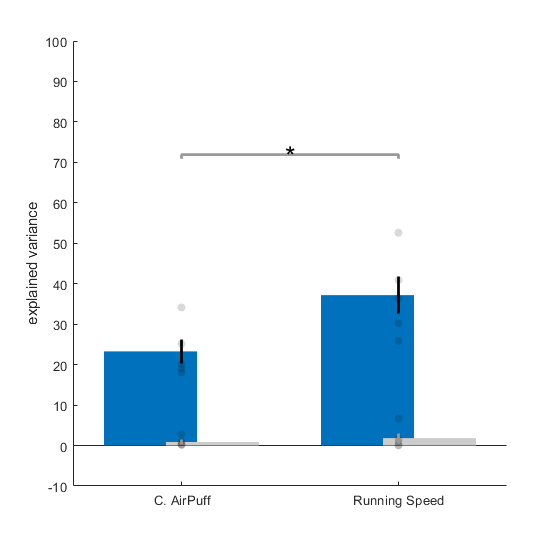

idx = 3

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


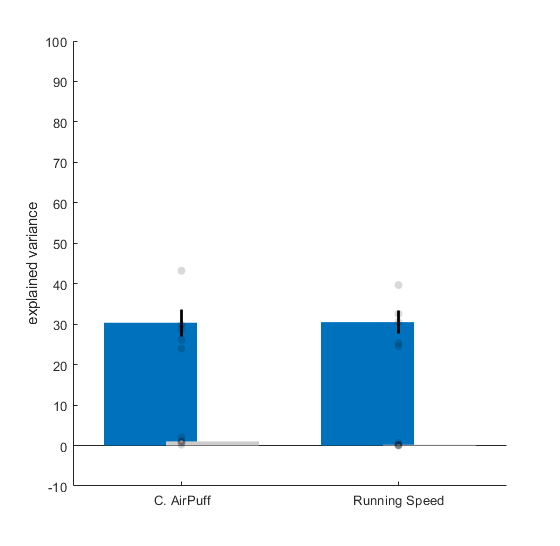

idx = 4

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


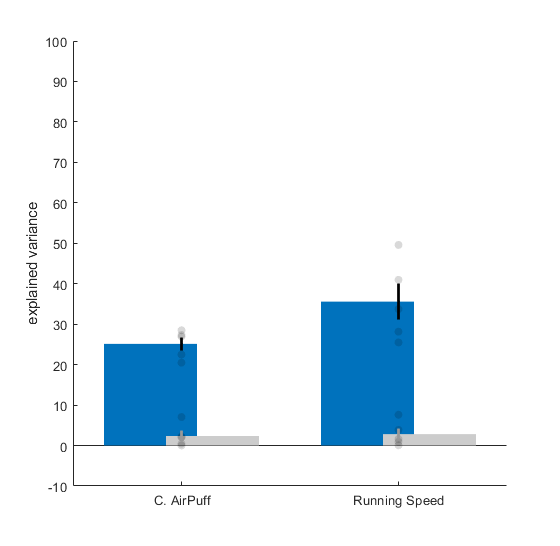

idx = 5

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


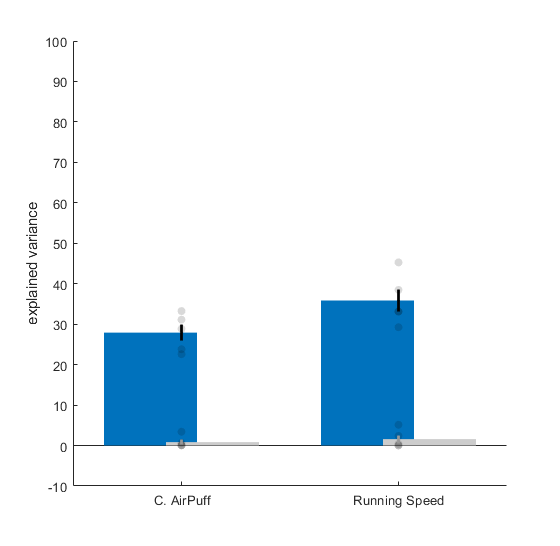

idx = 6

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


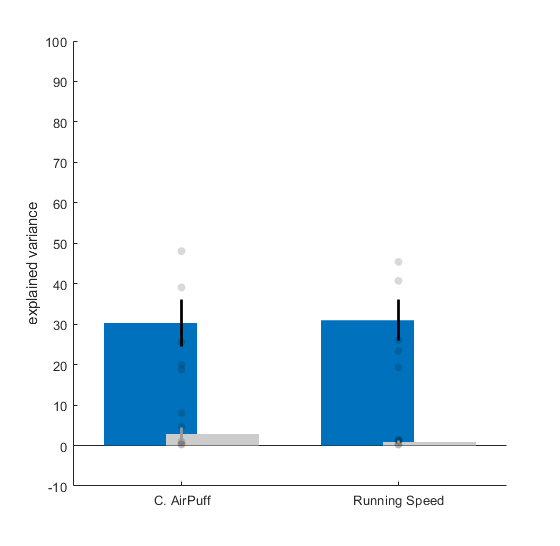

idx = 7

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


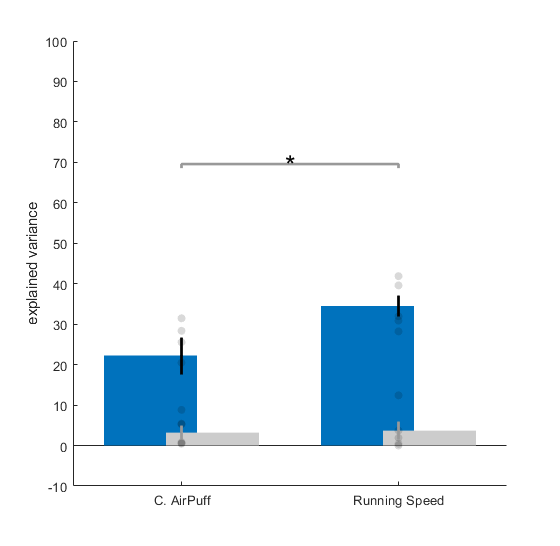

idx = 8

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


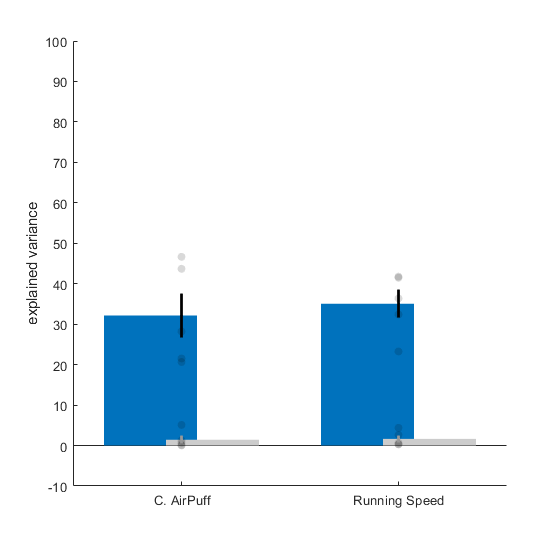

idx = 9

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


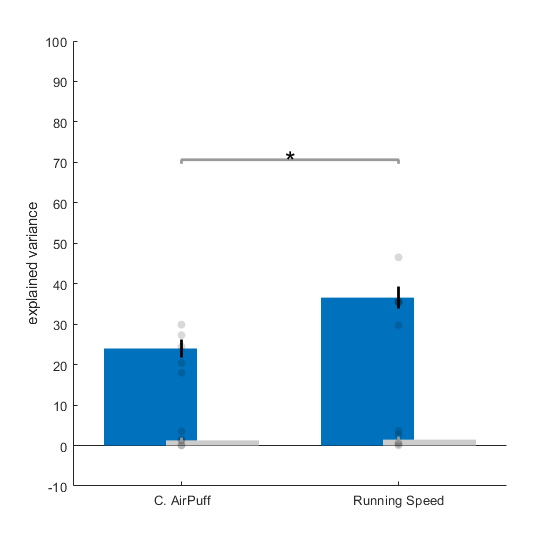

idx = 10

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


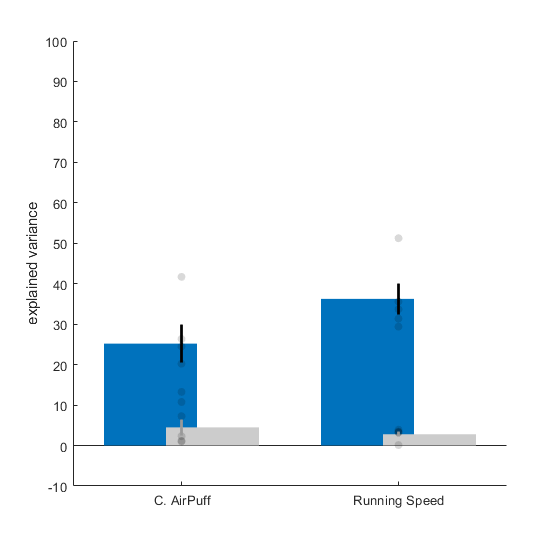

result_kfold = {};
for idx = 2:10
    idx
    result_kfold{idx} = predict_behaviours(obj,...
                                    predictors_type,...
                                    behaviours,...
                                    [],...
                                    ml_parameters,...
                                    'kfold', idx,...
                                    'block_shuffling',0); % We cannot have block shuffing AND kfold
end

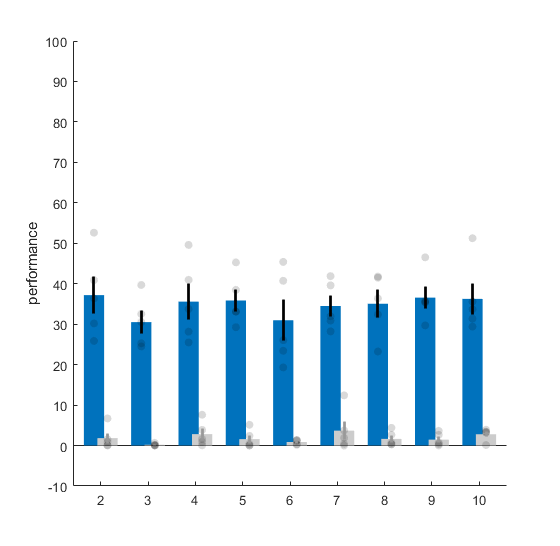

p = 0.89101; Conditions do not significantly differ from each other


bar_chart(result_kfold(2:end), 'encoder','','',arrayfun(@(x) num2str(x), 2:10,'UniformOutput',false));

## Test 1.2 : Test how the Holdout setting affect the prediction

Changing the holdout parameter from 0.1 to 0.9 (color scheme), with 10 iterations (individual points as scatter), for two behaviours. For example 0.2 means 20% kept for validation, 80% used for training

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


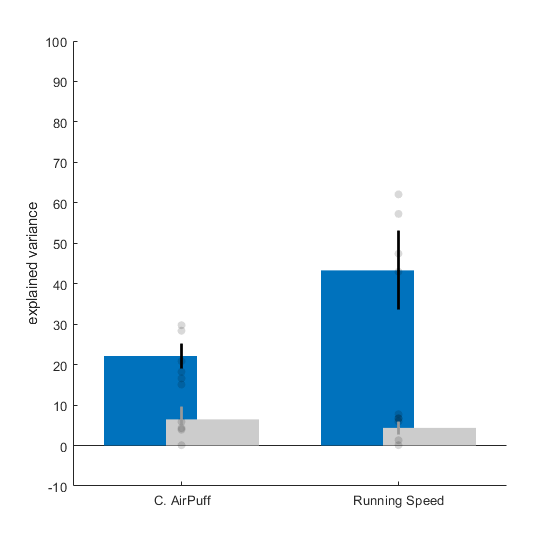

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


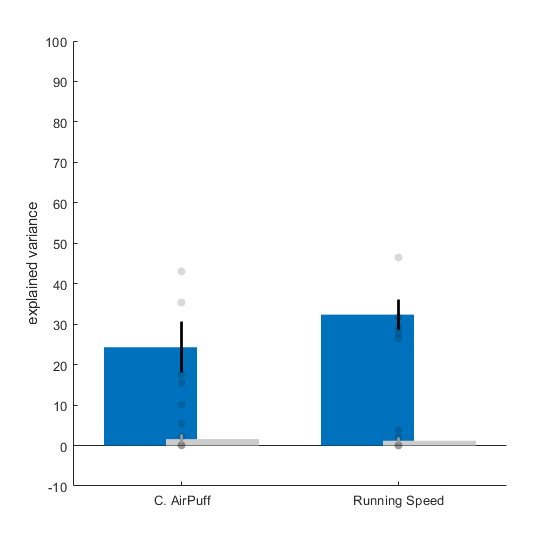

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


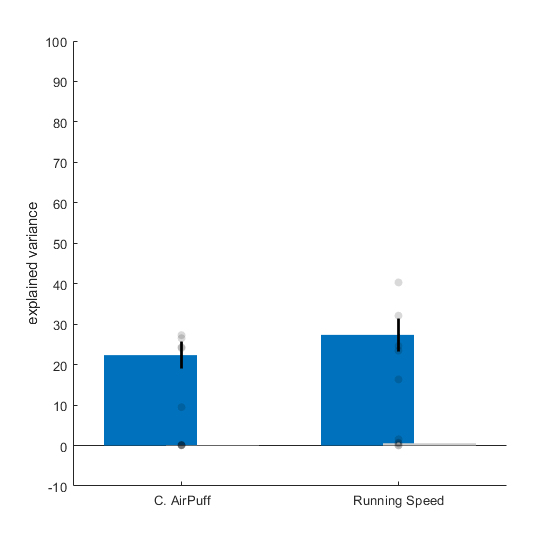

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


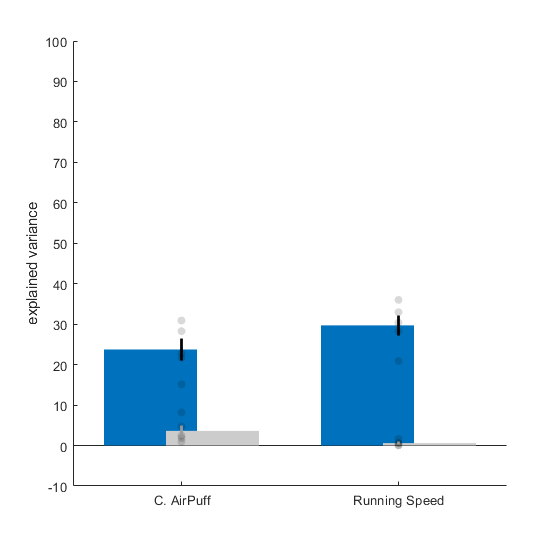

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


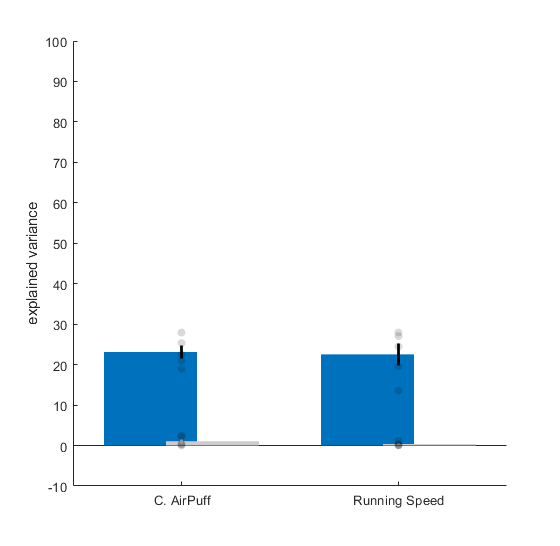

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


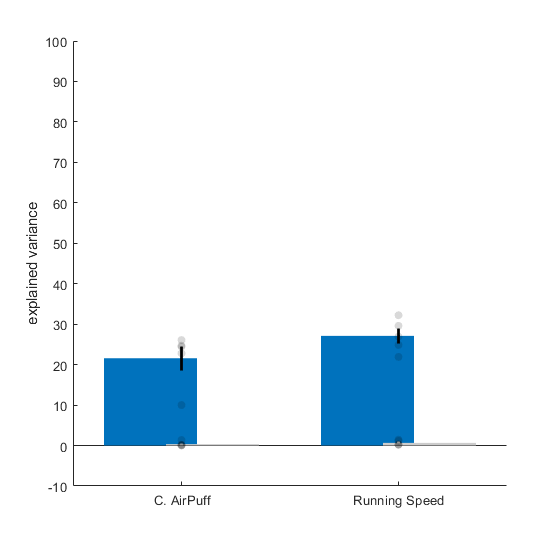

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


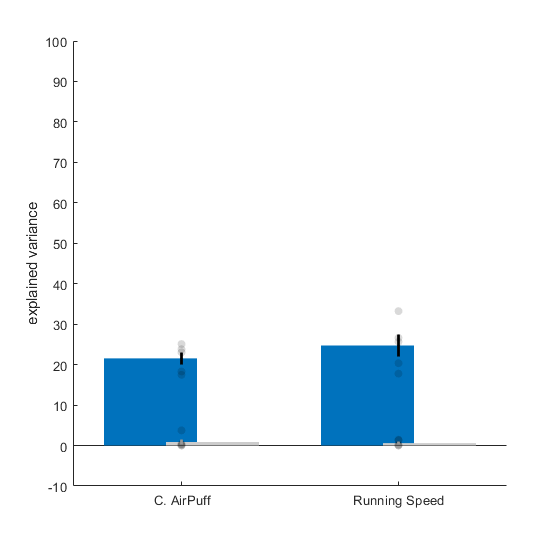

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


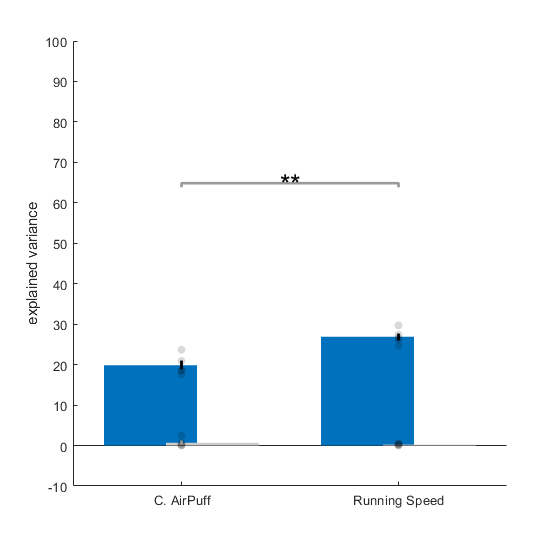

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


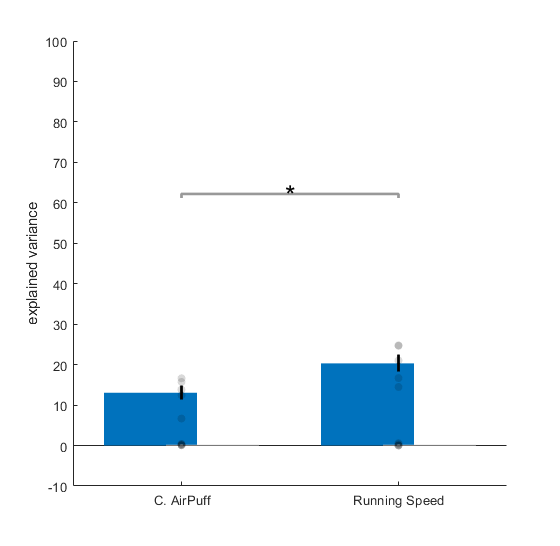

holdout_range = linspace(0.1,0.9,9);
result_holdout = {};
for idx = 1:numel(holdout_range) 
    result_holdout{idx} = predict_behaviours(obj,...
                                    predictors_type,...
                                    behaviours,...
                                    [],...
                                    ml_parameters,...
                                    'holdout', holdout_range(idx));
end

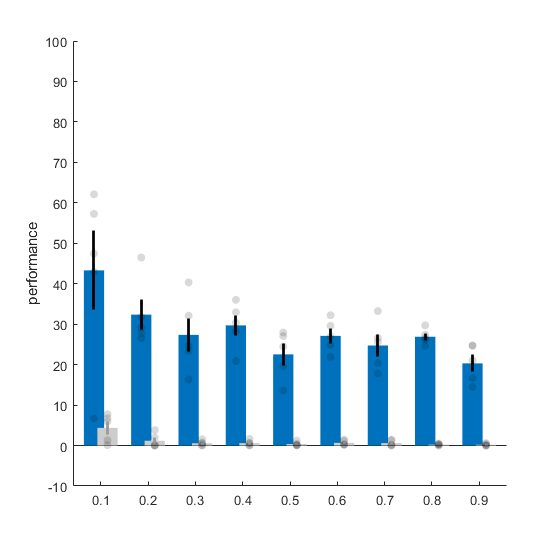

p = 0.075551; Conditions do not significantly differ from each other


bar_chart(result_holdout, 'encoder','','',arrayfun(@(x) num2str(x), holdout_range,'UniformOutput',false));

## Test 1.3 : Test how good is the hyperparameter optimization

Without hyperparameter optimization, with hyperparameter optimization using Matlab's method, with hyperparameter optimization using my custom grid search method, 10 iterations, two behaviours

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


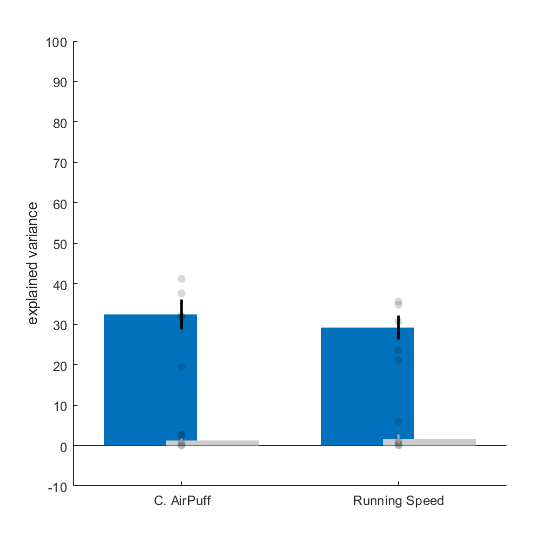

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


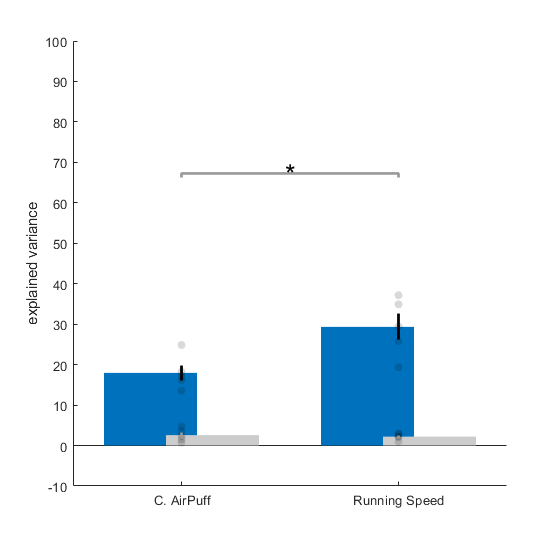

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


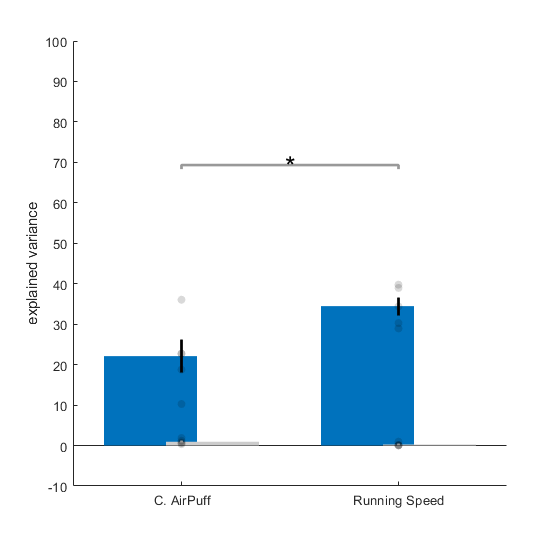

opti_range = [false, true, true];
method_list = {'', 'manual', 'native'};
result_hyper = {};
for idx = 1:numel(opti_range)  
    result_hyper{idx} = predict_behaviours(obj,...
                                    predictors_type,...
                                    behaviours,...
                                    [],...
                                    ml_parameters,...
                                    'optimize_hyper', opti_range(idx),...
                                    'optimization_method', method_list(idx));
end

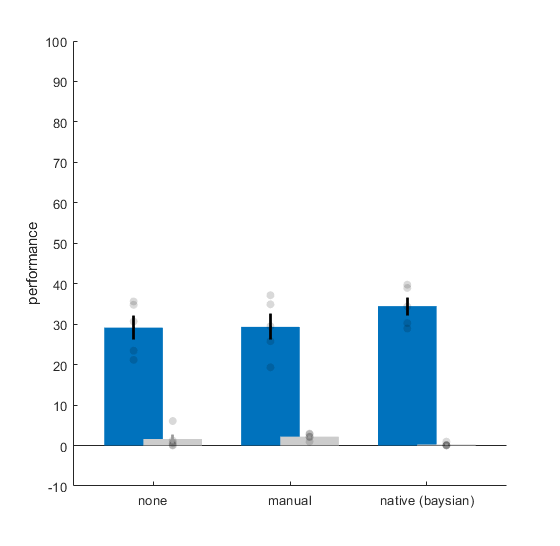

p = 0.47237; Conditions do not significantly differ from each other


bar_chart(result_hyper, 'encoder','','',{'none', 'manual', 'native (baysian)'});

## Test 1.4 : Test how different solvers affect the prediction

solver_list = {'sgd','asgd','lbfgs',{'sgd','lbfgs'},{'asgd','lbfgs'}};
result_solver = {};
for idx = 1:numel(solver_list)  
    result_solver{idx} = predict_behaviours(obj,...
                                    predictors_type,...
                                    behaviours,...
                                    [],...
                                    ml_parameters,...
                                    'solver', solver_list(idx));
end

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1


Unrecognized field name "postfit_bias".

Error in prediction (line 71)
                            'PostFitBias'   , ml_parameters.postfit_bias,...

Error in train_and_test (line 148)
        [y_predict, y_test, ~, x_test, x_train, y_train, model] = prediction(predictor_data(roi_subset,:), current_obs, partit

bar_chart(result_solver, 'encoder','','',{'sgd','asgd','lbfgs','sgd + lbfgs','asgd + lbfgs'});

## Test 1.5 : Test the impact of the post-fit Bias

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


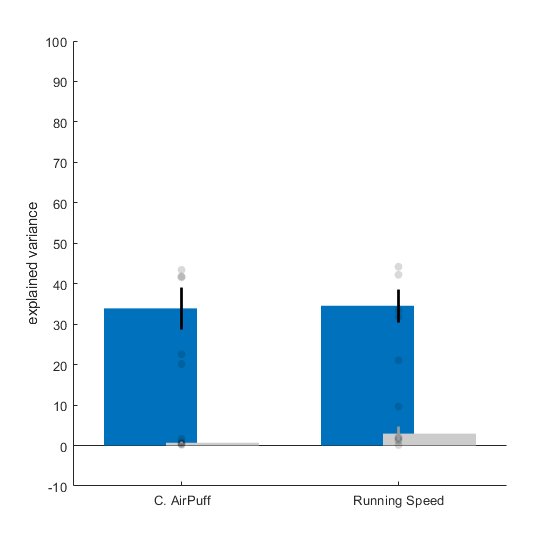

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
the two conditions are significantly different


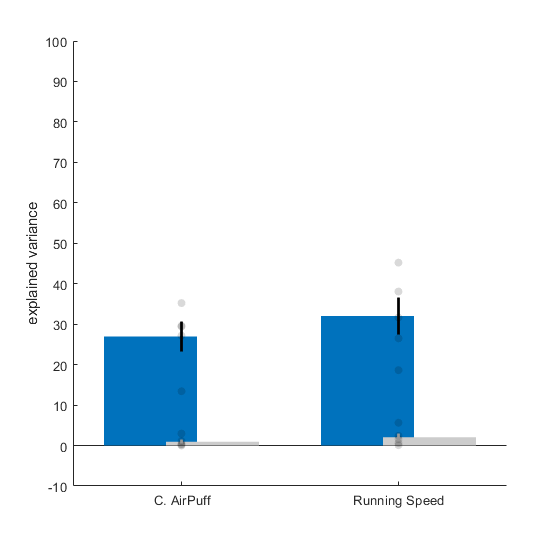

postfit_bias = [false, true];
result_postfit = {};
for idx = 1:numel(postfit_bias)  
    result_postfit{idx} = predict_behaviours(obj,...
                                    predictors_type,...
                                    behaviours,...
                                    [],...
                                    ml_parameters,...
                                    'postfit_bias', postfit_bias(idx));
end

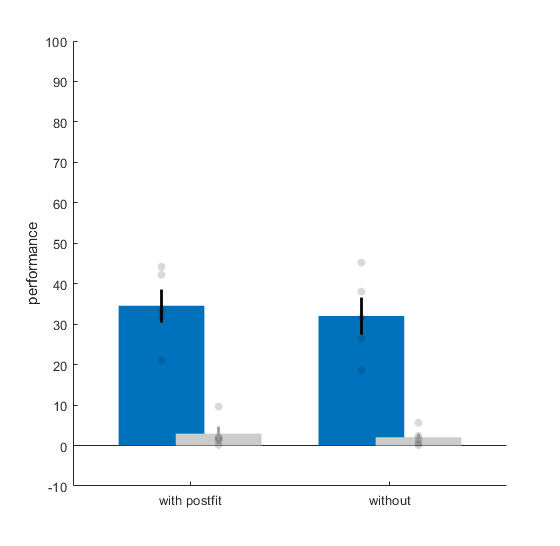

the two conditions are significantly different


bar_chart(result_postfit, 'encoder','','',{'with postfit', 'without'});

# 2. Test the effect of shuffling

## Test 2.1 : Test the effect of behaviour shuffling

% % Using the entire dendritic tree on the encoder
% multirunRL = {};
% for iter = 1:10
%     multirunRL{iter} = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'encoder','L_whisker','L_whisker_shuffle'}, '', 'optimize_hyper', true, 'optimization_method', 'manual');
% end

block_size = 100

The out-of-sample misclassification rate is 4.81%
The out-of-sample misclassification rate is 3.36e+09%
The out-of-sample misclassification rate is 1.32e+10%


block_size = 100

The out-of-sample misclassification rate is 4.82%
The out-of-sample misclassification rate is 5.58e+09%
The out-of-sample misclassification rate is 7.16e+09%


block_size = 100

The out-of-sample misclassification rate is 4.19%
The out-of-sample misclassification rate is 3.53e+09%
The out-of-sample misclassification rate is 8.9e+09%


block_size = 100

The out-of-sample misclassification rate is 4.39%
The out-of-sample misclassification rate is 2.97e+09%
The out-of-sample misclassification rate is 1.31e+10%


block_size = 100

The out-of-sample misclassification rate is 3.5%
The out-of-sample misclassification rate is 3.5e+09%
The out-of-sample misclassification rate is 9.09e+09%


block_size = 100

The out-of-sample misclassification rate is 5.06%
The out-of-sample misclassification rate is 3.43e+09%
The out-of-sample misclassification rate is 8.39e+09%


block_size = 100

The out-of-sample misclassification rate is 4.22%
The out-of-sample misclassification rate is 3.97e+09%
The out-of-sample misclassification rate is 7.59e+09%


block_size = 100

The out-of-sample misclassification rate is 3.86%
The out-of-sample misclassification rate is 3.46e+09%
The out-of-sample misclassification rate is 7.97e+09%


block_size = 100

The out-of-sample misclassification rate is 4.01%
The out-of-sample misclassification rate is 4.22e+09%
The out-of-sample misclassification rate is 7.73e+09%


block_size = 100

The out-of-sample misclassification rate is 4.58%
The out-of-sample misclassification rate is 3.79e+09%
The out-of-sample misclassification rate is 1.4e+10%


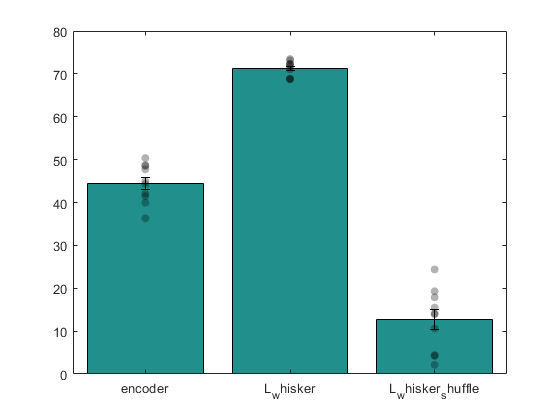

% bar_chart(multirunRL);

## Test 2.2 : Test the effect of shuffling predictor timpoints

block_size = 100

The out-of-sample misclassification rate is 4.89%
The out-of-sample misclassification rate is 7.25e+09%
The out-of-sample misclassification rate is 8.22e+09%


block_size = 100

The out-of-sample misclassification rate is 4.99%
The out-of-sample misclassification rate is 7.75e+09%
The out-of-sample misclassification rate is 8.05e+09%


block_size = 100

The out-of-sample misclassification rate is 5.82%
The out-of-sample misclassification rate is 1.06e+10%
The out-of-sample misclassification rate is 8.04e+09%


block_size = 100

The out-of-sample misclassification rate is 12.1%
The out-of-sample misclassification rate is 6.96e+09%
The out-of-sample misclassification rate is 7.78e+09%


block_size = 100

The out-of-sample misclassification rate is 5.34%
The out-of-sample misclassification rate is 9.38e+09%
The out-of-sample misclassification rate is 7.49e+09%


block_size = 100

The out-of-sample misclassification rate is 4.78%
The out-of-sample misclassification rate is 7.64e+09%
The out-of-sample misclassification rate is 8.71e+09%


block_size = 100

The out-of-sample misclassification rate is 18.3%
The out-of-sample misclassification rate is 1.36e+10%
The out-of-sample misclassification rate is 8.1e+09%


block_size = 100

The out-of-sample misclassification rate is 6.48%
The out-of-sample misclassification rate is 7.5e+09%
The out-of-sample misclassification rate is 7.19e+09%


block_size = 100

The out-of-sample misclassification rate is 5.52%
The out-of-sample misclassification rate is 1.06e+10%
The out-of-sample misclassification rate is 8.85e+09%


block_size = 100

The out-of-sample misclassification rate is 7.66%


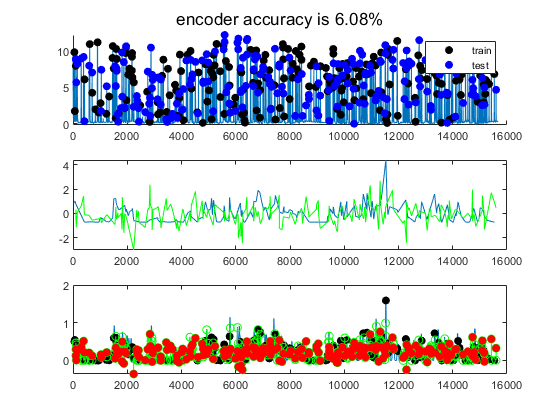

The out-of-sample misclassification rate is 1.19e+10%


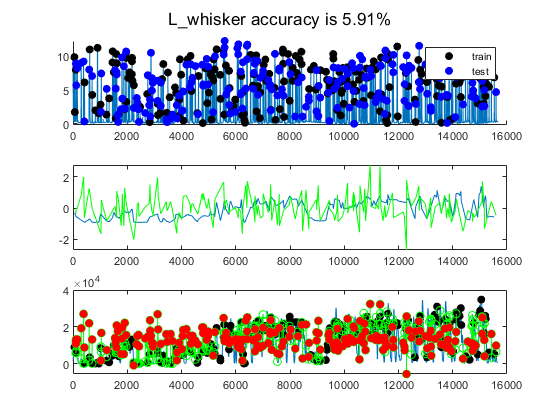

The out-of-sample misclassification rate is 9.13e+09%


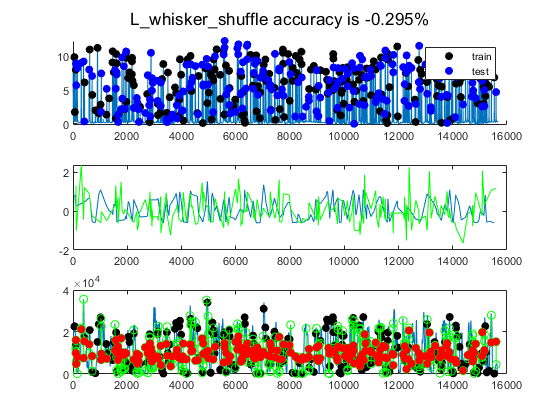

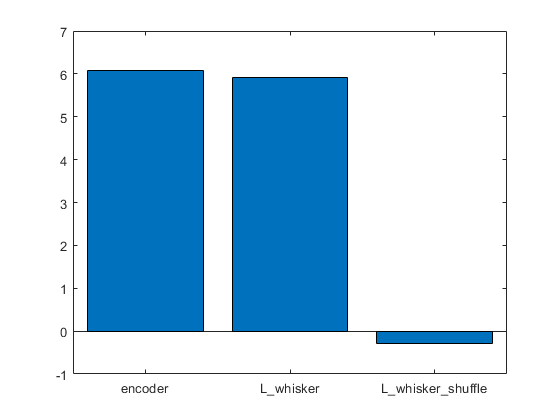

% % Using the entire dendritic tree on the encoder
% multirunRL = {};
% for iter = 1:10
%     multirunRL{iter} = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'encoder','L_whisker','L_whisker_shuffle'}, '', 'optimize_hyper', true, 'optimization_method', 'manual','shuffling','events');
% end

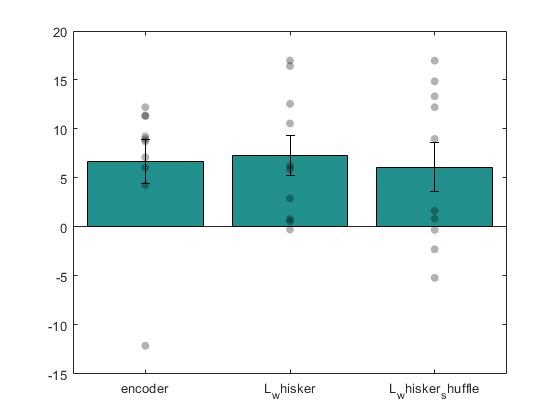

% bar_chart(multirunRL);

## Test 2.3 : Test the effect of shuffling modulation values

block_size = 100

The out-of-sample misclassification rate is 21.4%
The out-of-sample misclassification rate is 7.49e+09%
The out-of-sample misclassification rate is 1.52e+10%


block_size = 100

The out-of-sample misclassification rate is 6.03%
The out-of-sample misclassification rate is 7e+09%
The out-of-sample misclassification rate is 1.46e+10%


block_size = 100

The out-of-sample misclassification rate is 5.69%
The out-of-sample misclassification rate is 1.3e+10%
The out-of-sample misclassification rate is 8.41e+09%


block_size = 100

The out-of-sample misclassification rate is 31.1%
The out-of-sample misclassification rate is 9.39e+09%
The out-of-sample misclassification rate is 7.92e+09%


block_size = 100

The out-of-sample misclassification rate is 28.6%
The out-of-sample misclassification rate is 1.03e+10%
The out-of-sample misclassification rate is 7.58e+09%


block_size = 100

The out-of-sample misclassification rate is 4.2%
The out-of-sample misclassification rate is 7.42e+09%
The out-of-sample misclassification rate is 1.22e+10%


block_size = 100

The out-of-sample misclassification rate is 6.21%
The out-of-sample misclassification rate is 9.97e+09%
The out-of-sample misclassification rate is 6.09e+09%


block_size = 100

The out-of-sample misclassification rate is 4.41%
The out-of-sample misclassification rate is 7.35e+09%
The out-of-sample misclassification rate is 9.93e+09%


block_size = 100

The out-of-sample misclassification rate is 12.7%
The out-of-sample misclassification rate is 7.12e+09%
The out-of-sample misclassification rate is 1.31e+10%


block_size = 100

The out-of-sample misclassification rate is 5.14%


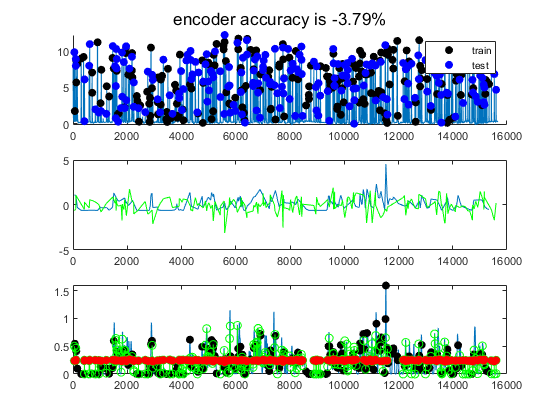

The out-of-sample misclassification rate is 7.15e+09%


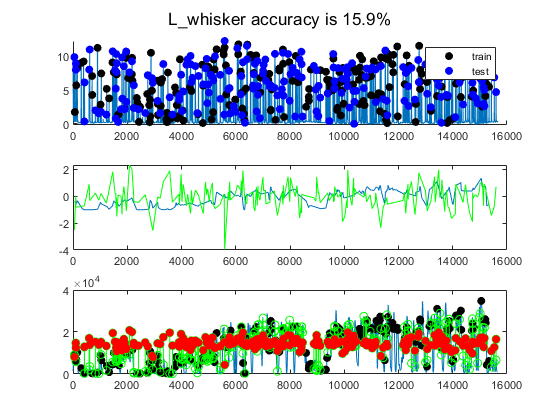

The out-of-sample misclassification rate is 8.72e+09%


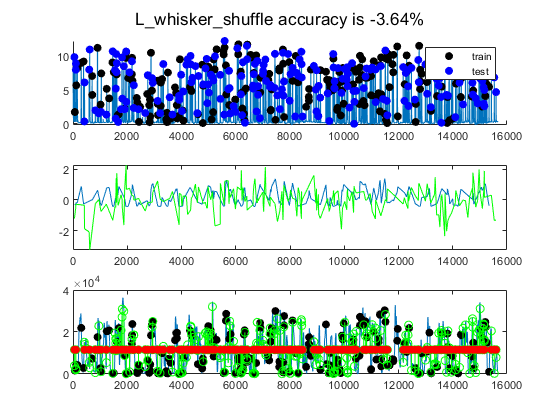

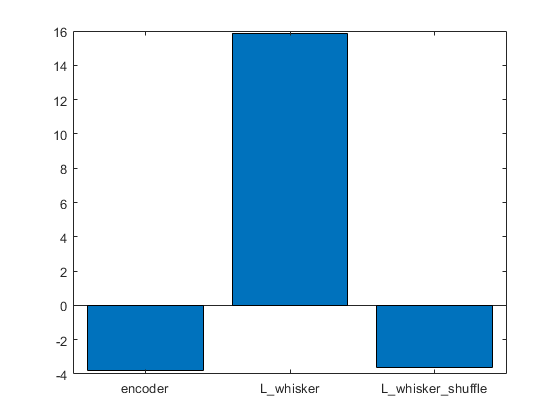

% % Using the entire dendritic tree on the encoder
% multirunRL = {};
% for iter = 1:10
%     multirunRL{iter} = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'encoder','L_whisker','L_whisker_shuffle'}, '', 'optimize_hyper', true, 'optimization_method', 'manual','shuffling','ROIs');
% end

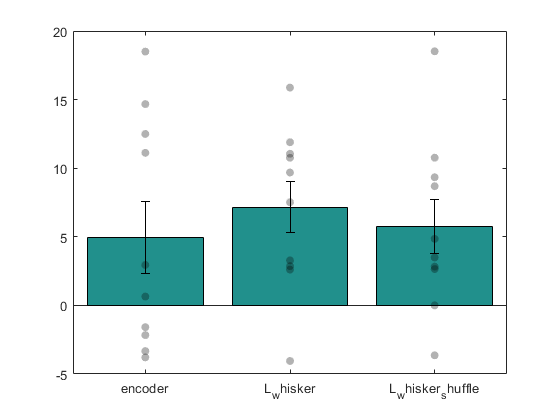

% bar_chart(multirunRL);

## Test 2.4 : Full shuffling

block_size = 100

The out-of-sample misclassification rate is 4.55%
The out-of-sample misclassification rate is 7.13e+09%
The out-of-sample misclassification rate is 1.06e+10%


block_size = 100

The out-of-sample misclassification rate is 5.2%
The out-of-sample misclassification rate is 6.78e+09%
The out-of-sample misclassification rate is 1.5e+10%


block_size = 100

The out-of-sample misclassification rate is 4.01%
The out-of-sample misclassification rate is 7.05e+09%
The out-of-sample misclassification rate is 7.33e+09%


block_size = 100

The out-of-sample misclassification rate is 19.8%
The out-of-sample misclassification rate is 7.7e+09%
The out-of-sample misclassification rate is 1.01e+10%


block_size = 100

The out-of-sample misclassification rate is 7.21%
The out-of-sample misclassification rate is 1.56e+10%
The out-of-sample misclassification rate is 6.52e+09%


block_size = 100

The out-of-sample misclassification rate is 4.71%
The out-of-sample misclassification rate is 1.65e+10%
The out-of-sample misclassification rate is 8.57e+09%


block_size = 100

The out-of-sample misclassification rate is 20.9%
The out-of-sample misclassification rate is 1.11e+10%
The out-of-sample misclassification rate is 7.95e+09%


block_size = 100

The out-of-sample misclassification rate is 4.77%
The out-of-sample misclassification rate is 8.39e+09%
The out-of-sample misclassification rate is 1.1e+10%


block_size = 100

The out-of-sample misclassification rate is 4.36%
The out-of-sample misclassification rate is 7.49e+09%
The out-of-sample misclassification rate is 1.95e+10%


block_size = 100

The out-of-sample misclassification rate is 4.84%


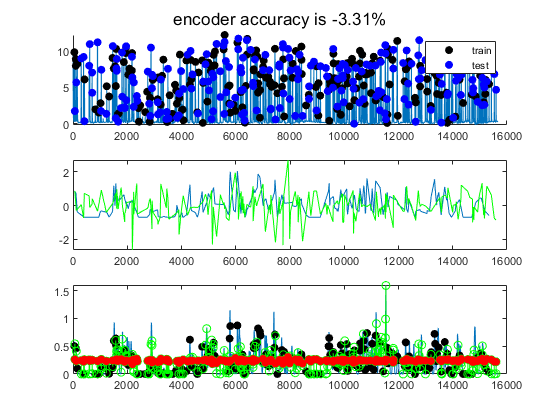

The out-of-sample misclassification rate is 7.51e+09%


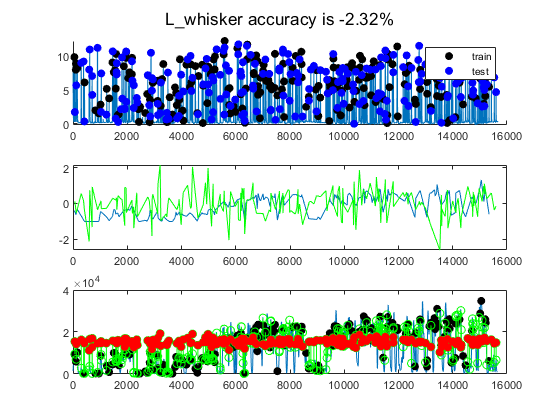

The out-of-sample misclassification rate is 1.56e+10%


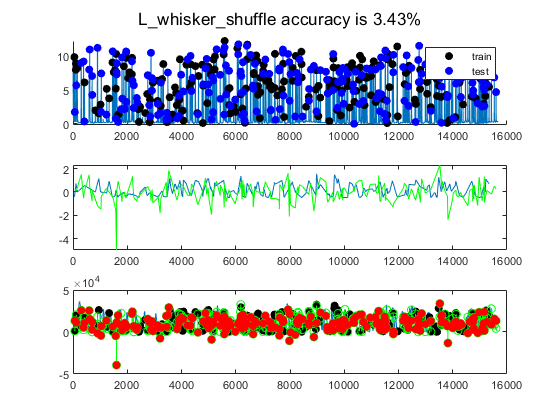

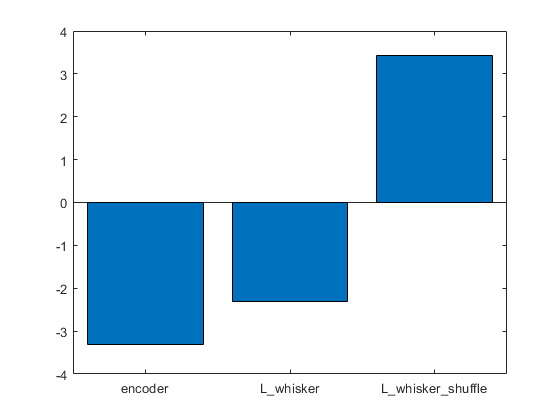

% % Using the entire dendritic tree on the encoder
% multirunRL = {};
% for iter = 1:10
%     multirunRL{iter} = predict_behaviours(obj, false, 'linear', 'peaks_subtracted',{'encoder','L_whisker','L_whisker_shuffle'}, '', 'optimize_hyper', true, 'optimization_method', 'manual','shuffling','both');
% end

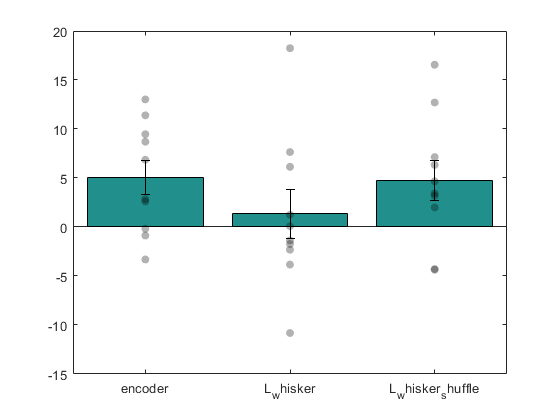

% bar_chart(multirunRL);

# 3. Extract the beta coefficients

## Test 3.1 : Test how good is the manual hyperparameter optimization for linear regression across behaviours

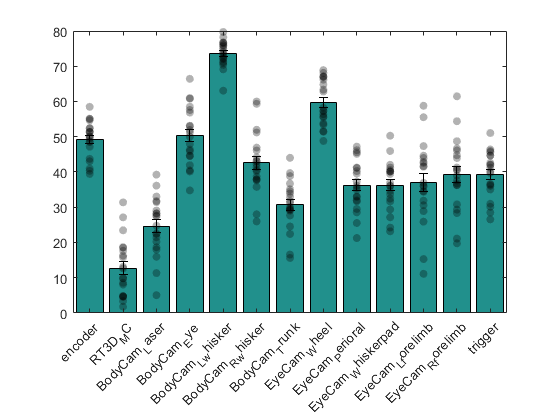

% result_beta = {};
% for iter = 1:20
%      result_beta{iter} = predict_behaviours(obj, false, 'linear', 'peaks_rescaled','', '', 'optimize_hyper', true, 'optimization_method', 'manual', 'rendering',0);
% end
% bar_chart(result_beta);

ans = 'encoder'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

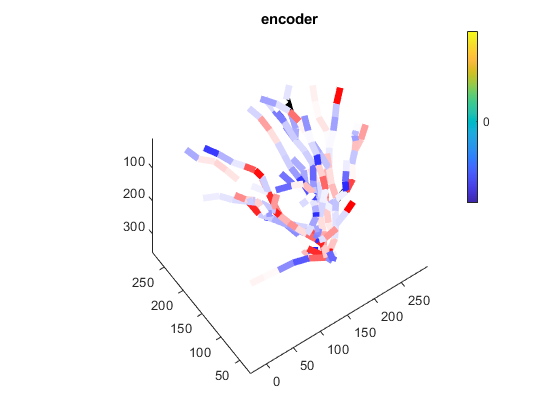

ans = 'RT3D_MC'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

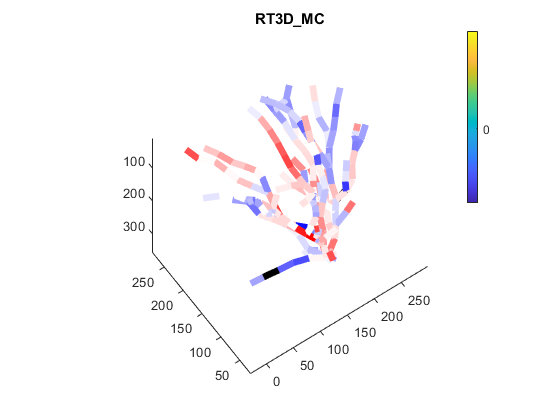

ans = 'BodyCam_Laser'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

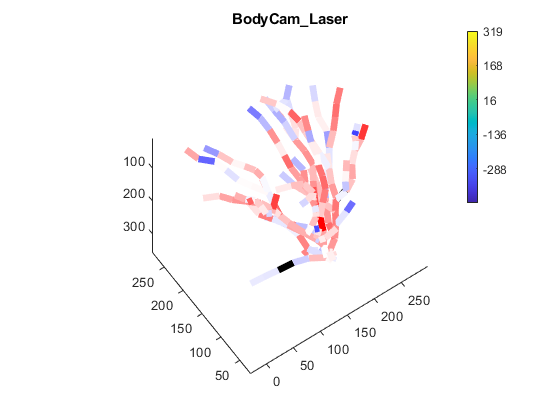

ans = 'BodyCam_Eye'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

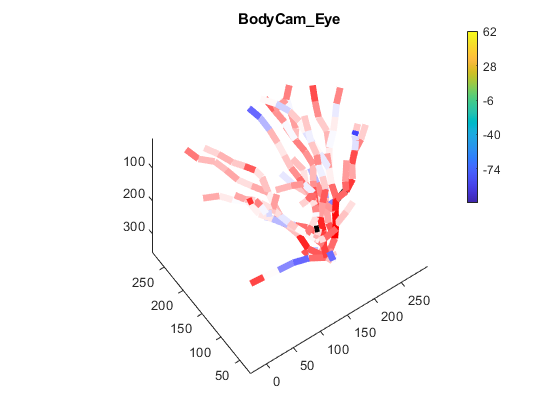

ans = 'BodyCam_L_whisker'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

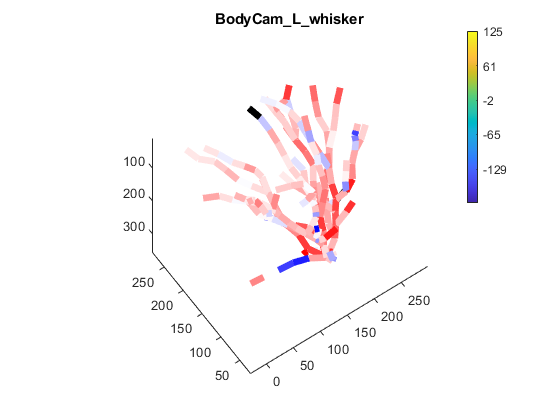

ans = 'BodyCam_R_whisker'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

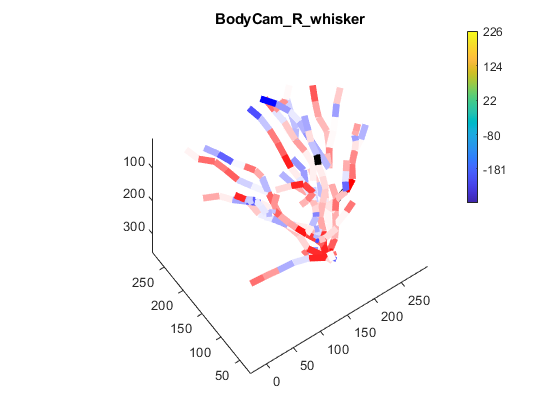

ans = 'BodyCam_Trunk'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

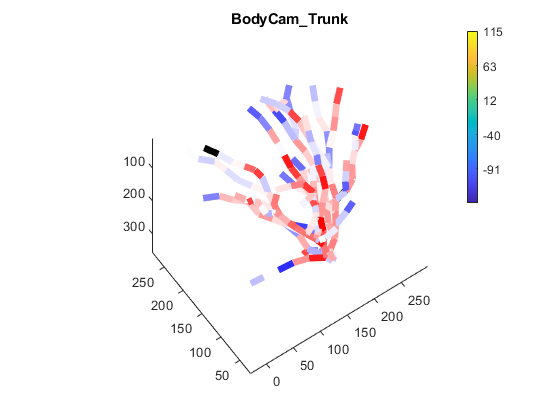

ans = 'EyeCam_Wheel'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

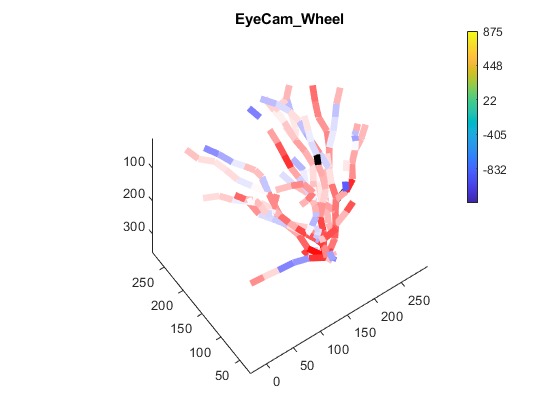

ans = 'EyeCam_Perioral'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

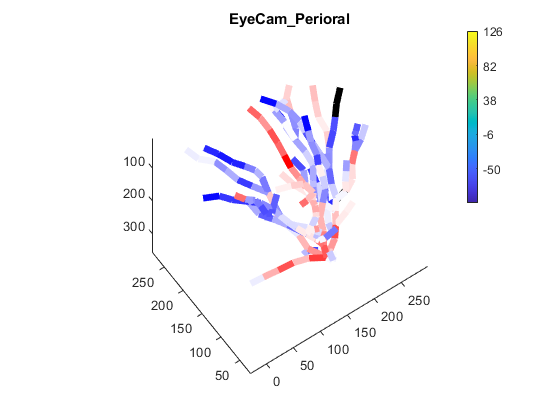

ans = 'EyeCam_Whiskerpad'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

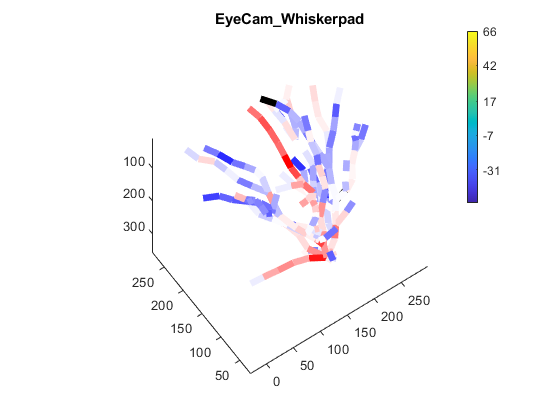

ans = 'EyeCam_L_forelimb'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

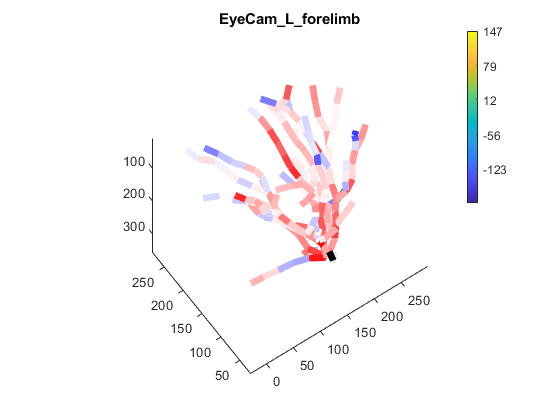

ans = 'EyeCam_R_forelimb'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

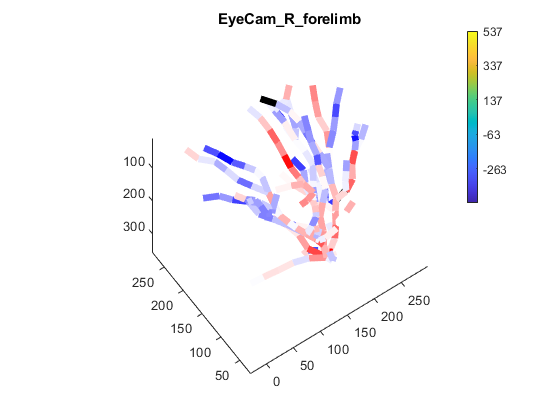

ans = 'trigger'

ans = 1

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

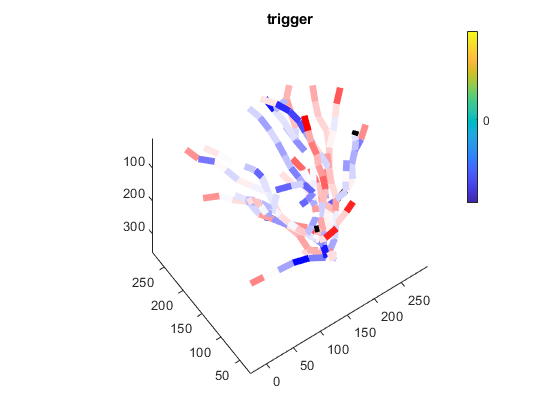

% for beh_idx = 1:numel(result_beta{1}.beh_type)
%     betas   = [];
%     for iter = 1:numel(result_beta)
%         model = result_beta{iter}.model{beh_idx};
%         for trained_idx = 1:numel(model.Trained)
%             mdl = model.Trained{trained_idx};                        
%             betas(trained_idx, :) = mdl.Beta;
%         end
%     end
%     result_beta{1}.beh_type{beh_idx}
%     next_fig
%     obj.ref.plot_value_tree(mean(betas,1), find(~ismember(obj.ref.indices.valid_swc_rois, obj.bad_ROI_list)),'',strrep(result_beta{1}.beh_type{beh_idx},'_','\_'),'',beh_idx,'','redblue', 'invalid_color_symetrical');
% end

Copying objective function to workers...
Done copying objective function to workers.
|================================================================================================|
| Iter | Active  | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | workers | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|================================================================================================|
|    1 |      18 | Best   |      21.982 |      1.5904 |      21.982 |      21.982 |        181.9 |
|    2 |      17 | Best   |      21.943 |      1.8555 |      21.943 |      21.975 |       43.502 |
|    3 |      17 | Accept |      21.998 |      1.6391 |      21.943 |      21.975 |       205.32 |
|    4 |       3 | Accept |      21.897 |      2.0089 |      21.863 |      21.924 |   6.6285e-07 |
|    5 |       3 | Accept |       21.92 |      2.0006 |      21.863 |      21.924 |       25.044 |
|    6 |       3 | Accep

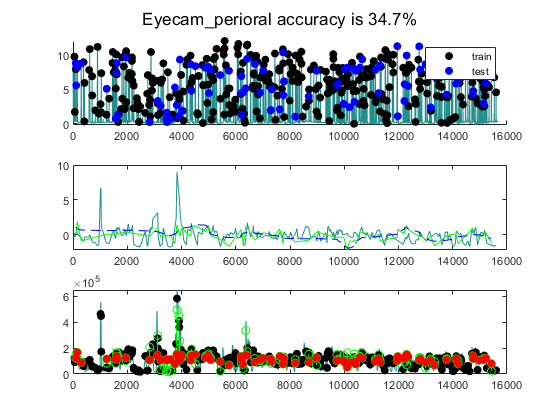

% a = {};
% for iter = 1:10
%      a{iter} = predict_behaviours(obj, false, 'linear', 'peaks_rescaled',{'Eyecam_perioral'}, '', 'optimize_hyper', true, 'optimization_method', 'native', 'rendering',2);
% end

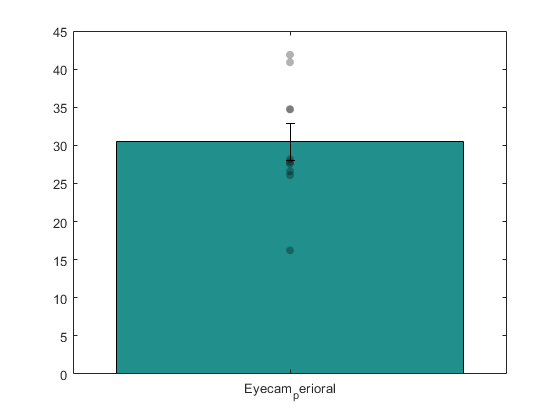

% bar_chart(a);

ans = 'Eyecam_perioral'

ans = 24

total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

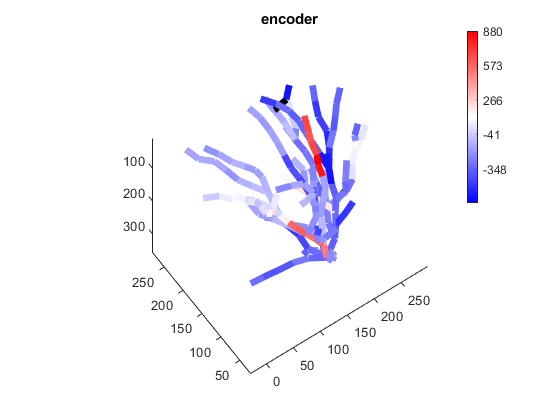

% for beh_idx = 1:numel(a{1}.beh_type)
%     betas   = [];
%     for iter = 1:numel(a)
%         model = a{iter}.model{beh_idx};
%         for trained_idx = 1:numel(model.Trained)
%             mdl = model.Trained{trained_idx};                        
%             betas(iter, trained_idx, :) = mdl.Beta;
%         end
%     end
%     a{1}.beh_type{beh_idx}
%     next_fig
%     obj.ref.plot_value_tree(mean(betas,1), find(~ismember(obj.ref.indices.valid_swc_rois, obj.bad_ROI_list)),'',strrep(result_beta{1}.beh_type{beh_idx},'_','\_'),'',beh_idx,'','redblue', 'invalid_color_symetrical');
% end

% 
% 
% 
% 
% 
% 
% 
% % plot_prediction(out{1}.calcium, out{1}.bin_beh{1}, out{1}.peak_tp{1}, out{1}.train_range{1}, out{1}.prediction{1}, out{1}.full_beh{1} , out{1}.beh_type{1}, out{1}.score{1});
